## Housekeeping

- confirm CODES path

- confirm DATA path - which day or multiple days are you processing

- get user email 

clearvars

global_dir = uigetdir('.', 'UAV Rectification');
cd(global_dir)
setenv('PATH', [getenv('PATH') ':/usr/local/bin']);

Check for CODES folder dependencies

%code_dir = [global_dir '/UAV_automated_rectification/CODES'];
code_dir = [global_dir '/CODES'];

% Check that required rectification codes are downloaded.
if ~exist([code_dir '/CIRN'], 'dir')
    disp('Please download CIRN codes from GitHub.')
end
% Check that cBathy codes are downloaded.
if ~exist([code_dir '/cBathy_2.0'], 'dir')
    disp('Please download cBathy v2.0 codes from GitHub.')
end
% Check that basic Functions are downloaded.

Please download cBathy v2.0 codes from GitHub.


if ~exist([code_dir '/basicFunctions'], 'dir')
    disp('Please download basicFunctions codes from GitHub.')
end

addpath(genpath(code_dir))

Load which data folders are to be processed

data_dir = [global_dir '/DATA'];

% Load in all days that need to be processed.
data_files = dir(data_dir); data_files([data_files.isdir]==0)=[]; data_files(contains({data_files.name}, '.'))=[];
[ind_datafiles,~] = listdlg('ListString',{data_files.name}, 'SelectionMode','multiple', 'InitialValue',1, 'PromptString', {'Which days would you like to process?'});
data_files = data_files(ind_datafiles);

Get user email

user_email = inputdlg({'Name', 'Email'});

props = java.lang.System.getProperties;
props.setProperty('mail.smtp.port', '587');
props.setProperty('mail.smtp.auth','true');
props.setProperty('mail.smtp.starttls.enable','true');

setpref('Internet','SMTP_Server','smtp.gmail.com');
setpref('Internet','SMTP_Username','athinalange1996');
setpref('Internet', 'SMTP_Password', 'baundwhnctgbsykb')
sendmail(user_email{2}, 'UAV Toolbox test email', [user_email{1} ' is processing UAV data from ' data_files.name '.'])

save([global_dir '/processing_run_' char(string(datetime('today')))], '*_dir', 'data_files', 'user_email')

## User Input 

- Choose camera intrinsics file (all flights for a given day must be used with the same drone)

- Grid & transect coordinates - can be input or from file

- Local or world coordinates?

- dx

% run user input code
user_input_data

## Extract IMAGES

requires: user_email  and data_files

ans = '2 Hz data can be pulled from 10 Hz data'

ans = '10 Hz data can be pulled from 10 Hz data'

    7 image files read


C = 7×11 table
                                              SourceFile                                                   FileName              CreateDate           Duration    CameraPitch    CameraYaw    CameraRoll    AbsoluteAltitude    RelativeAltitude             GPSLatitude                      GPSLongitude         
    _______________________________________________________________________________________________    ________________    _______________________    ________    ___________    _________    __________    ________________    ________________    _____________________________    ______________________________

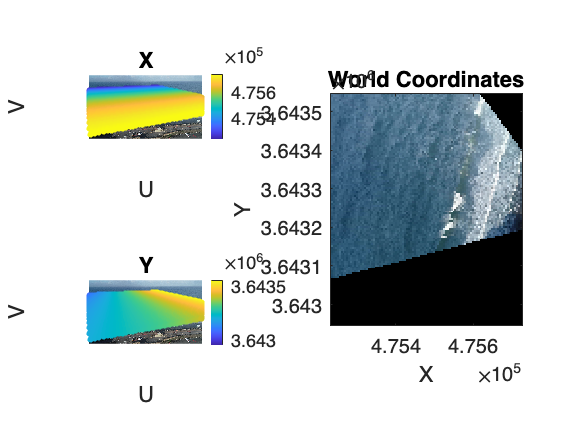

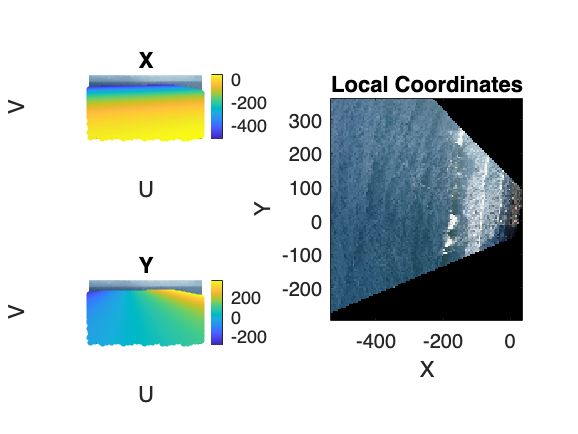

jj =      0


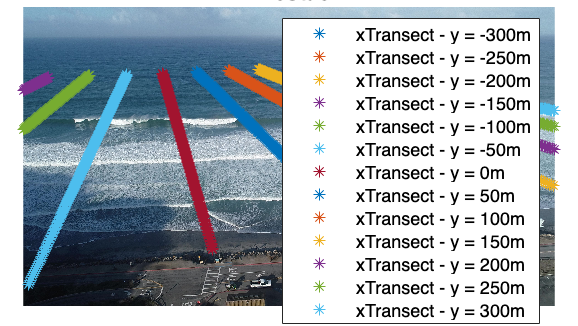

grid_text = 1×2 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475831.66, 3643235.46, 66.52, 5.05, 1.22, 0.00'}


grid_text = 1×3 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475831.66, 3643235.46, 66.52, 5.05, 1.22, 0.00'}    {'Extract data at 10 Hz. '}


grid_text = 1×4 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475831.66, 3643235.46, 66.52, 5.05, 1.22, 0.00'}    {'Extract data at 10 Hz. '}    {'Products to produce:'}


    8 image files read


C = 8×11 table
                                              SourceFile                                                   FileName              CreateDate           Duration    CameraPitch    CameraYaw    CameraRoll    AbsoluteAltitude    RelativeAltitude             GPSLatitude                      GPSLongitude         
    _______________________________________________________________________________________________    ________________    _______________________    ________    ___________    _________    __________    ________________    ________________    _____________________________    ______________________________

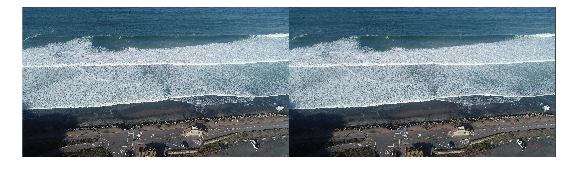

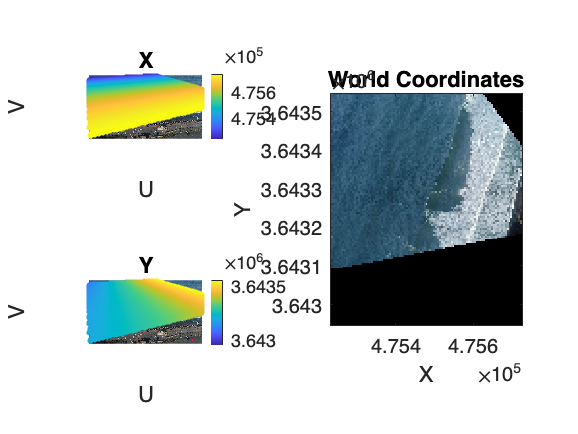

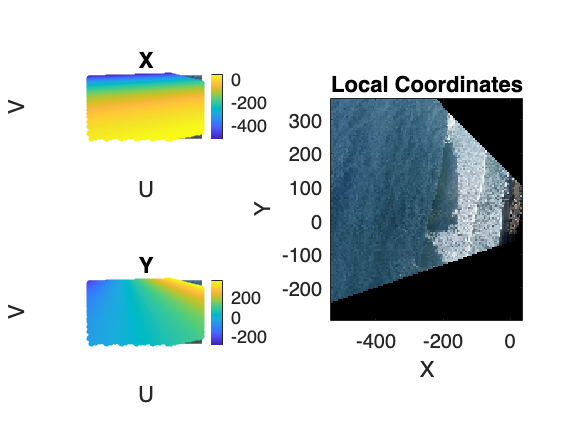

jj =      0


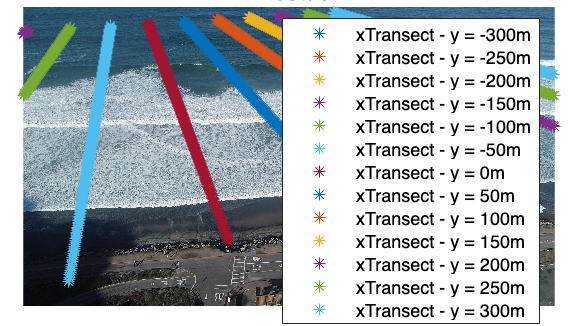

grid_text = 1×2 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475829.13, 3643229.68, 88.08, 5.09, 1.06, 0.00'}


grid_text = 1×3 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475829.13, 3643229.68, 88.08, 5.09, 1.06, 0.00'}    {'Extract data at 10 Hz. '}


grid_text = 1×4 cell array
    {'Lat / Long = 32.93 / -117.26, Angle = 262.01 deg'}    {'Initial Extrinsics Guess: 475829.13, 3643229.68, 88.08, 5.09, 1.06, 0.00'}    {'Extract data at 10 Hz. '}    {'Products to produce:'}


%extract_images